**Numerical Methods **

-    Making sense out of our data

-    Cleaning up noisey data

-     Making geusses/approximations from our data

Interpolation - geussing/approximating within our data

Liner Data

Start with a new figure

clear
clc
close all

figure  
clf

hold on %Plotting multiple graphs on one set of axes


Original plot

x = [1 2 3 4];
y =[1 3 2 4 ];
plot(x,y,'r.:','markersize',24) 
axis([0 5 0 5])
title('Interpolation of linear data using interp1() and spline()')
xlabel('x')
ylabel('y')

Points on the x axis where I want to interpolate values for y

newx = [1.5 2.5 3.5];
text(newx, [0 0 0],'X')

interp1 - linear interpolation

newyI = interp1(x,y,newx);
plot(newx, newyI, 'g.', 'markersize', 24)

spline - piecewise polynomial interpolation

newyS = spline(x,y,newx);
plot(newx, newyS, 'b.', 'markersize', 24)


Calculated data points

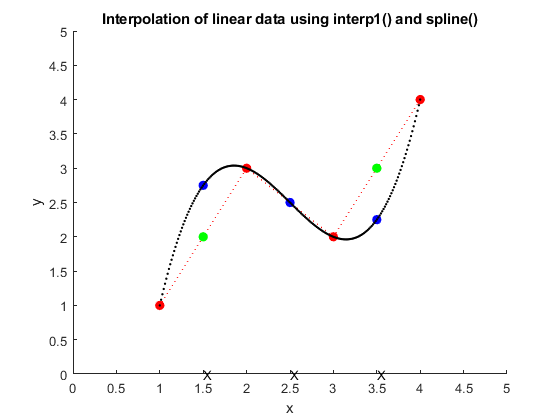

newx = linspace(1,4,200);
newyS = spline(x,y,newx);
plot(newx, newyS, 'k.', 'markersize', 5)

Non Linear Data

Start with new figure

figure  
clf
hold on %Plotting multiple graphs on one set of axes


Original plot

theta = [0 45 90 135 180 225 270 315 360];
y = cosd(theta);
plot(theta, y, 'r.', 'markersize', 24);
title('Interpolation of nonlinear data using interp1() and spline()')
xlabel('Theta')
ylabel('y')


Points on the x axis where I want to interpolate values for y

newtheta = [15 30 60 75 105 120 150 165 195 210 240 255 285 300 330 345];
text(newtheta,-ones(1,length(newtheta)),'X')


interp1 - linear interpolation

newy = interp1(theta,y,newtheta);
plot(newtheta, newy, 'g.', 'markersize', 24)
plot(newtheta, newy, 'g-', 'linewidth', 1)


spline - piecewise polynomial interpolation

newyS = spline(theta,y,newtheta);
plot(newtheta, newyS, 'b.', 'markersize', 24)
plot(newtheta, newyS, 'b-', 'linewidth', 1)


Calculated data points

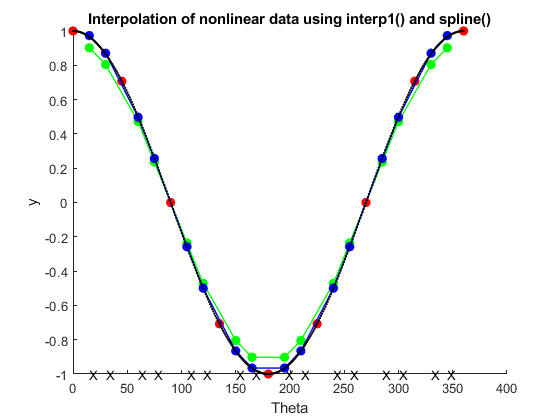

alltheta = linspace(0,360,360);
ally = cosd(alltheta);
plot(alltheta, ally, 'k.', 'markersize', 5)